$\min 20x + 25 y$ st 


$$2x+3y\geq 18\\
x+3y\geq 12\\ 
4x+3y\geq 24\\
x,y\geq 0.$$
 

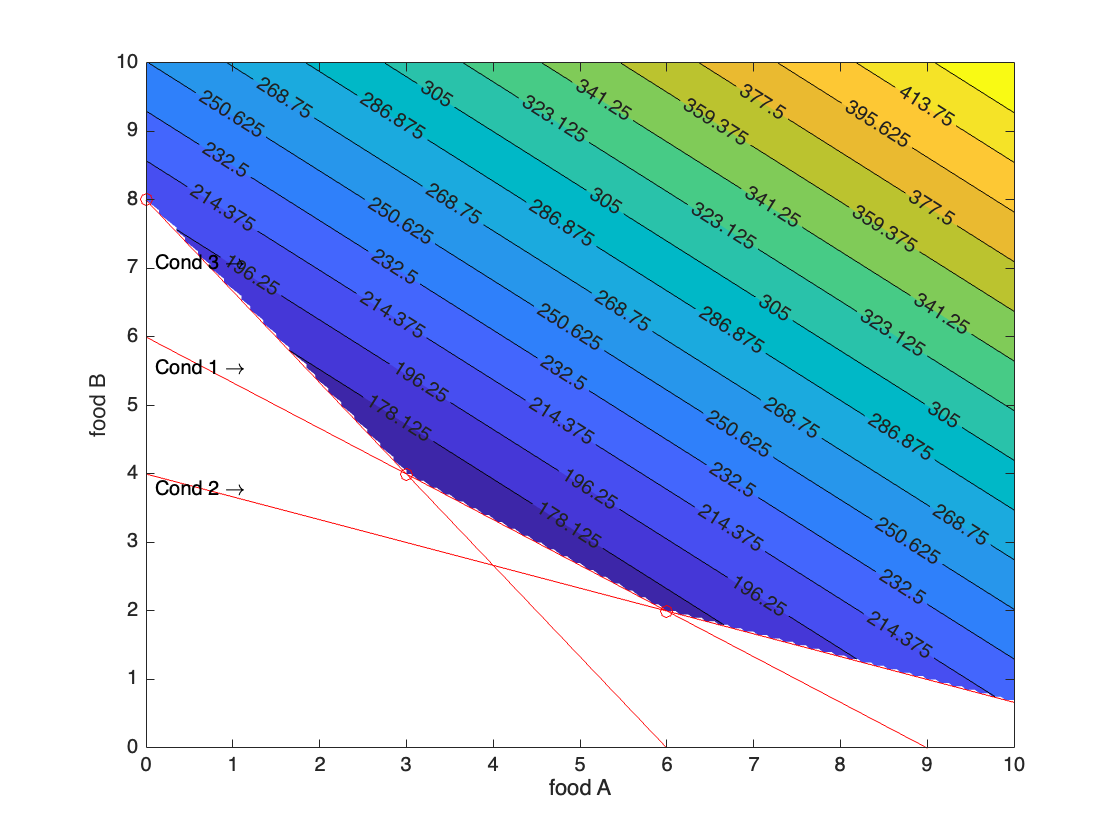

clear;clc
%Generate data
x = 0:0.05:10;
[A,B] = meshgrid(x);
NB=20*A+25*B;

% Get True where condition aplies, false where not.
cond1=2*A+3*B>=18;
cond2=A+3*B>=12;
cond3 = 4*A + 3 * B >= 24;
% Get boundaries of the condition
Cp1=(18-2*x)/3;
Cp2=(12-x)/3;
Cp3=(24-4*x)/3;

%Delete Areas whereCondition does not apply;
NB(~cond1)=NaN;
NB(~cond2)=NaN;
NB(~cond3) = NaN;
%% Plot
[C,h]=contourf(A,B,NB,15);
clabel(C,h,'LabelSpacing',100) % optional
hold on

plot(0,8, 'ro')
plot(3,4, 'ro')
plot(6,2, 'ro')

plot(x,Cp1,'r-')
text(A(1,3),Cp1(15), 'Cond 1 \rightarrow'); %arbitrary location

plot(x,Cp2,'r-')
text(A(1,3),Cp2(15), 'Cond 2 \rightarrow'); %arbitrary location

plot(x,Cp3,'r-')
text(A(1,3),Cp3(15), 'Cond 3 \rightarrow'); %arbitrary location
axis([0 10 0 10])
xlabel('food A')
ylabel('food B')